### Data preparation

clear;
% Load dataset
load("PickPlaceYOLOChallengeHiddenIgnore\ChallengeTaskHiddenIgnore_T.mat");  % Change the directory if needed
canDataset = data_struct.canTrainingData;

% Random shuffle all images
rng(0);
shuffledIndices = randperm(height(canDataset));
idx = floor(0.8 * length(shuffledIndices));

% Split train, validation and test data: 0.8, 0.1, 0.1
trainingIdx = 1:idx;
validationIdx = idx + 1: idx + 1 + floor(0.1 * length(shuffledIndices));
testIdx = validationIdx(end) + 1: length(shuffledIndices);

trainingDataTbl = canDataset(shuffledIndices(trainingIdx), :);
validationDataTbl = canDataset(shuffledIndices(validationIdx), :);
testDataTbl = canDataset(shuffledIndices(testIdx), :);

imdsTrain = imageDatastore(trainingDataTbl.imageFilename);
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));
imdsValidation = imageDatastore(validationDataTbl.imageFilename);
bldsValidation = boxLabelDatastore(validationDataTbl(:, 2:end));
imdsTest = imageDatastore(testDataTbl.imageFilename);
bldsTest = boxLabelDatastore(testDataTbl(:, 2:end));

trainDataStore= combine(imdsTrain, bldsTrain);
validationDataStore = combine(imdsValidation, bldsValidation);
testDataStore = combine(imdsTest, bldsTest);

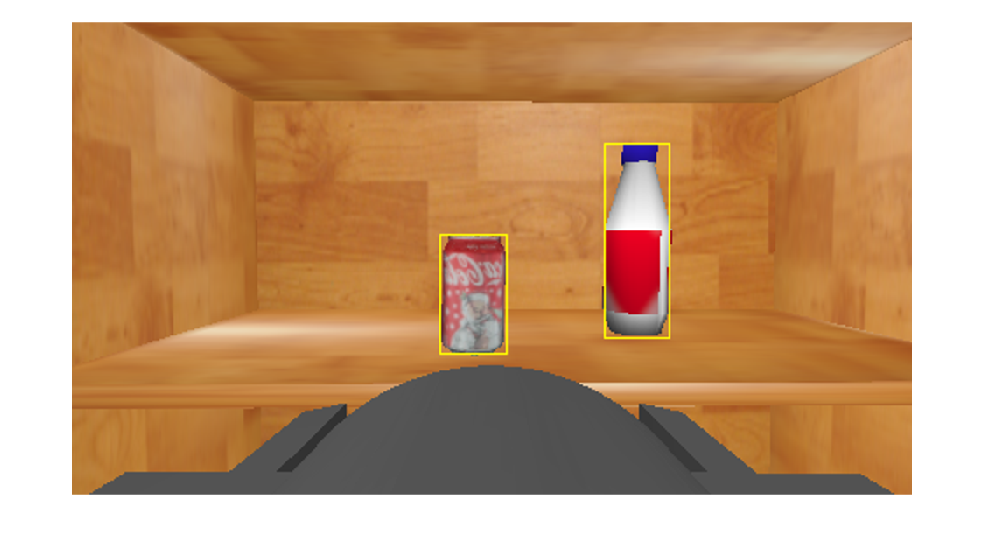

% Check the annotated images
data = read(trainDataStore);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

### Try using resnet-50 as backbone

Follow the example [Object Detection Using YOLO v2 Deep Learning - MATLAB & Simulink - MathWorks China](https://ww2.mathworks.cn/help/deeplearning/ug/object-detection-using-yolo-v2.html).

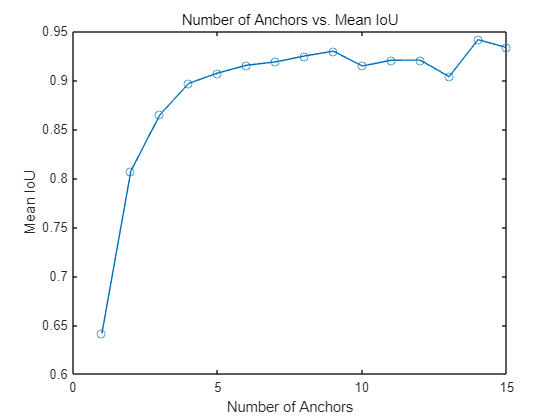

% Set the input size and output classes for the network
inputSize = [224 224 3];
numClasses = 2;
trainingDataForEstimation = transform(trainDataStore, @(data)preprocessData(data, inputSize));

% Estimate anchor boxes. Since number of anchor boxes is an empirical
% parameter, we plot the IoU performance to select the most efficient.
maxNumAnchors = 15;
meanIoU = zeros([maxNumAnchors, 1]);
anchorBoxes_trail = cell(maxNumAnchors, 1);

for k=1:maxNumAnchors
    [anchorBoxes_trail{k}, meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation, k);
end

figure
plot(1:maxNumAnchors,meanIoU,'-o')
ylabel("Mean IoU")
xlabel("Number of Anchors")
title("Number of Anchors vs. Mean IoU")


% Select number of anchors to use
numAnchors = 7;  % Currently following the tutorial
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)  % Plot all anchor sizes

anchorBoxes =     60    19
   103    20
    47    14
    80    12
    52    16
    91    17
   119    23


meanIoU = 0.9185

% Construct the network
featureExtractionNetwork = resnet50;
featureLayer = 'activation_40_relu';
lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

% Data augmentation
augmentedTrainingData = transform(trainDataStore, @augmentData);

% Append the augmented data to the original data.
trainstore = combine(trainDataStore, augmentedTrainingData, ReadOrder='sequential');

### Train and test network

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* bottle
* can

在单 CPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　６．７２　｜　　　　　　２．５１　｜　４５．１８４１　｜　６．３１０５　｜　　０．００１０　｜
｜　　　３　｜　　　５０　｜　　　　　００：０５：４６　｜　　　　　　　０．６４　｜　　　　　　０．６０　｜　　０．４１２７　｜　０．３６５１　｜　　０．００１０　｜
｜　　　５　｜　　１００　｜　　　　　００：１１：２０　｜　　　　　　　０．２８　｜　　　　　　０．３２　｜　　０．０７９９　｜　０．１０４５　｜　　０．００１０　｜
｜　　　８　｜　　１５０　｜　　　　　００：１６：５９　｜　　　　　　　０．２０　｜　　　　　　０．２１　｜　　０．０４１９　｜　０．０４４５　｜　　０．００１０　｜
｜　　１０　｜　　２００　｜　　　　　００：２２：３９　｜　　　　　　　０．２２　｜　　　　　　０．１９　｜　　０．０４８８　｜　０．０３７０　｜　　０．００１０　｜
｜　　１３　｜　　２５０　｜　　　　　００：２８：１０　｜　　　　　　　０．１５　｜　　　　　　０．１７　｜　　０．

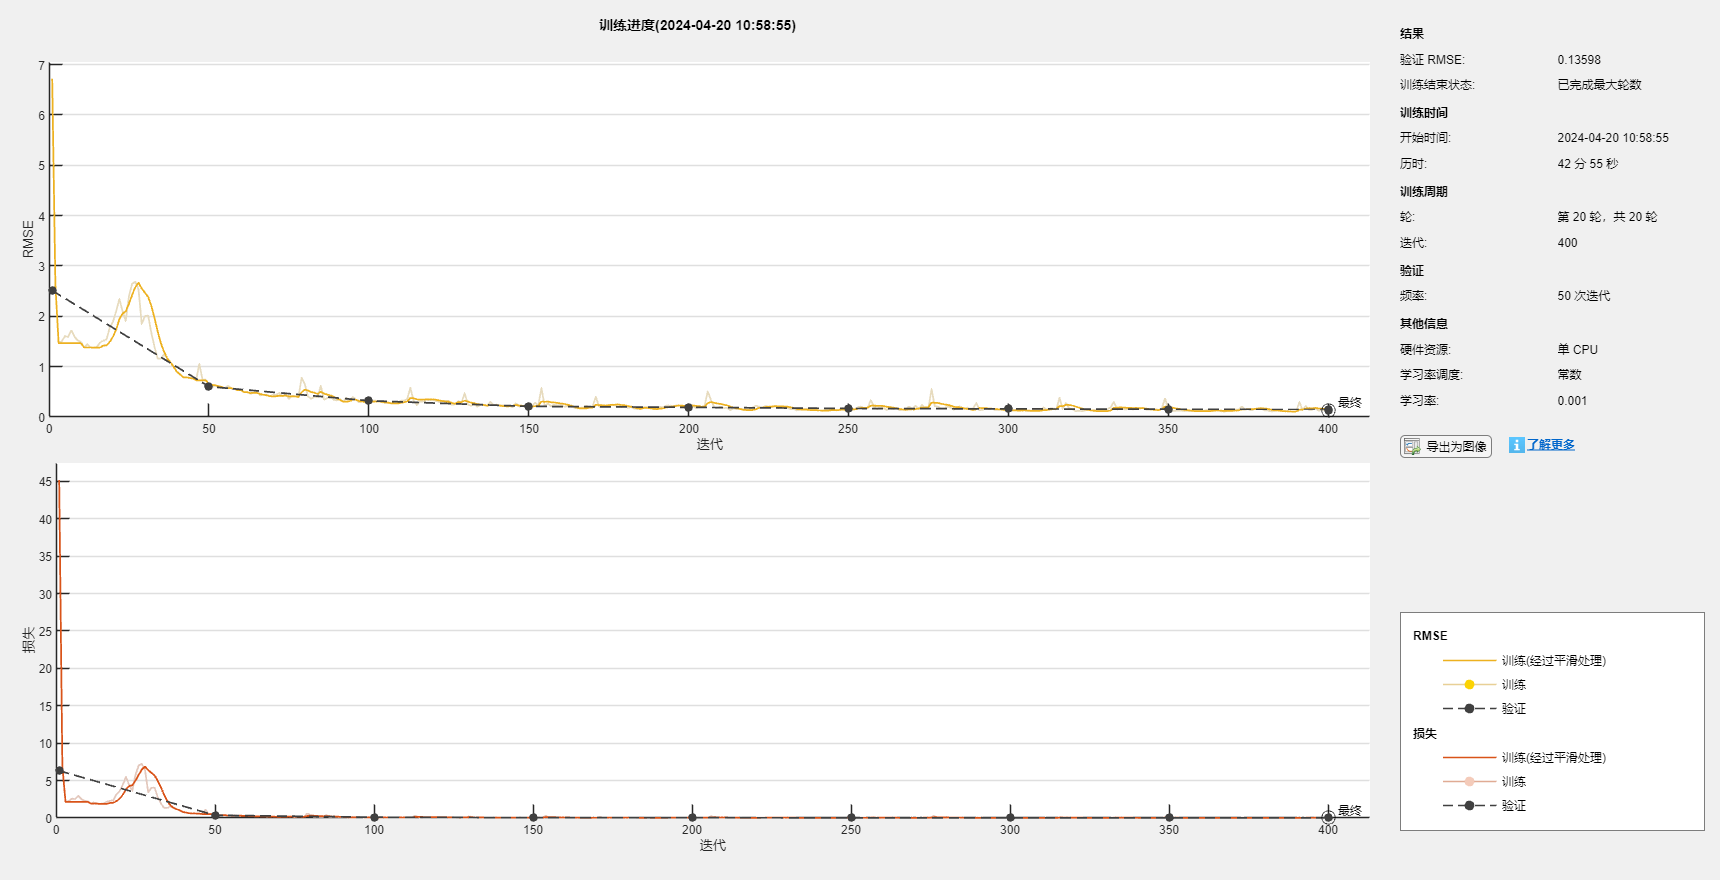

% Configure training options
options = trainingOptions('sgdm',...
          'InitialLearnRate',1e-3,...
          'LearnRateDropFactor', 0.1,...
          'LearnRateDropPeriod', 10,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',20,...
          'VerboseFrequency',50,...
          'CheckpointPath', 'checkpoint',...
          'Shuffle', 'every-epoch', ...
          'Plots','training-progress', ...
          'ValidationData', validationDataStore);

% Train the network
[detector,info] = trainYOLOv2ObjectDetector(trainstore,lgraph,options);

% Plot training losses
detector

detector =   yolov2ObjectDetector - 属性:

            ModelName: 'bottle'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [224 224]
          AnchorBoxes: [7×2 double]
           ClassNames: [bottle    can]


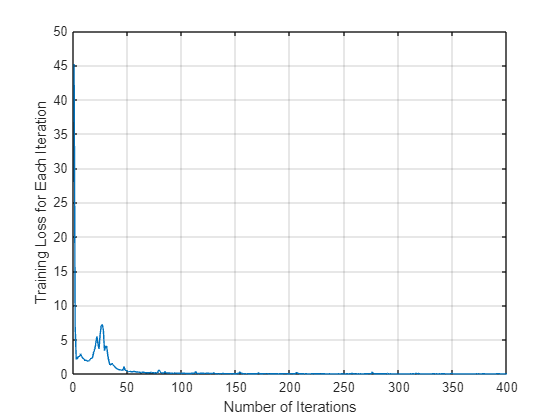

figure
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss for Each Iteration')

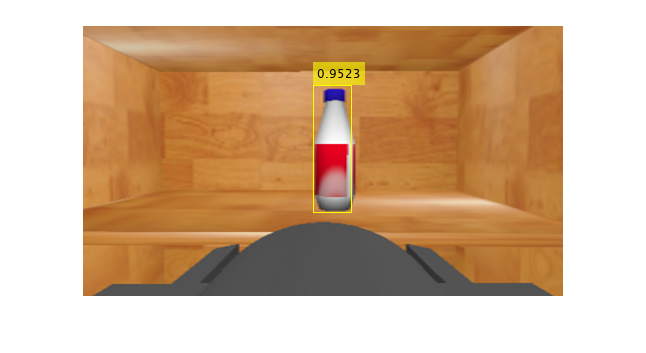

% Test on one image
img = imread("ImageSetChallenge\shot71.png");
img = imresize(img, inputSize(1:2));
[bboxes,scores] = detect(detector,img);


% Resize the output bbox and image to original size.
resized_bbox = bboxes;
original_size = [270, 480];
resized_bbox(:, 1) = bboxes(:, 1) * original_size(1, 2) / inputSize(1, 2);
resized_bbox(:, 2) = bboxes(:, 2) * original_size(1, 1) / inputSize(1, 1);
resized_bbox(:, 3) = bboxes(:, 3) * original_size(1, 2) / inputSize(1, 2);
resized_bbox(:, 4) = bboxes(:, 4) * original_size(1, 1) / inputSize(1, 1);

img = imresize(img, original_size);

if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',resized_bbox,scores);
end
figure
imshow(img)

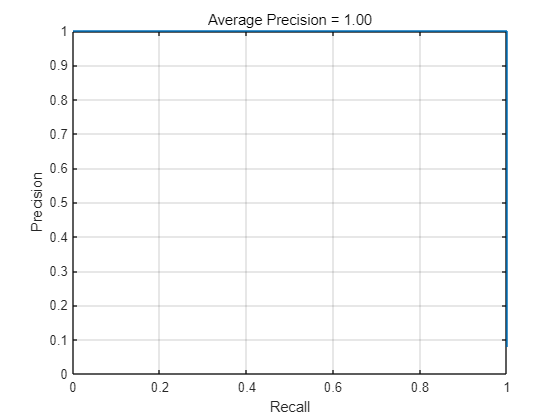

% Examine on test set
preprocessedTestData = transform(testDataStore,@(data)preprocessData(data,inputSize));

detectionThreshold = 0.01;
detectionResults = detect(detector, preprocessedTestData, Threshold=detectionThreshold);

metrics = evaluateObjectDetection(detectionResults,preprocessedTestData);

classID = 'can';
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",metrics.ClassMetrics.mAP(classID)))

% Save detector
detector.ModelName = 'challengeHiddenIgnore';
save("ChallengeTaskDetectorHiddenIgnore.mat", "detector");

### Helper functions used in this script

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
A{2} = helperSanitizeBoxes(A{2});

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
data{2} = helperSanitizeBoxes(data{2});

% Resize boxes to new image size.
data{2} = bboxresize(data{2},scale);
end